## Blind dereverberation exploiting Cross-Relation of Monoral System on the TF-representation

clear

settings

% DGT tool
F = DGTtool("windowLength", 512, "windowShift", 128);

% audio data loading
%path = "input/4077_13754_2sec_11025";
path = "input/Goldberg_clav";
fpaths = dir(path);
ss = cell(2,1);
for i=1:2
    audiofilename = path + "/" + fpaths(i+2).name;
    [temp, fs] =  audioread(audiofilename);
    noise = randn(size( temp(:,1) ));
    noise = 0.1 * noise * norm(temp(:,1)) / norm(noise);
    ss{i} = temp(:,1) + noise;
end
snr(temp(:,1), noise)

ans = 20

lambda = 1e-10;
s = [ss{1}; ss{2}];
num_mic = 1;

% ir data loading
% ir_data_path = "BFTLSPACELIBRARY_ChamberAL_11025.wav"; % RT60 = 1.89
%ir_data_path = "../data/wavIR/IR_sweep_15s_45Hzto22kHz_FS16kHz.v370.wav" %
%RT60 = 0.45
ir_data_path = "../data/wavIR/01.0s Villa Bathroom-OST.wav" % RT60 = 1.0

ir_data_path = "../data/wavIR/01.0s Villa Bathroom-OST.wav"

[ir, ~] = audioread(ir_data_path);
%[ir, fs] = audioread("logic03sWoodenBooth8000.wav");
%[ir, fs] = audioread("../data/BF TL SPACE LIBRARY/Drumbrella/Drumbrella 5'.R.wav");

Malloc

rt = zeros(1,1); % reverb time in sec
obs = cell(1,2); % obs
X = cell(1, 2); % STFTs of obs. signal
S = cell(1, 2); % STFTs of dry signal
N = zeros(1, 2); % length of obserbation
Lir = zeros(1, 1); % ir length = d + 1
l = zeros(1, 2); % length of deconvoluted signal

## resample and shortening

% calcurate the reververation time (RT60)
rt = reverb_time(ir, fs);
ir = ir(1:floor(fs*rt)); ir = ir(:) / norm(ir);
IR = F(ir);
Lir = size(IR, 2);

for j = 1:2
    obs{j} = conv(ss{j}, ir);
    X{j} = F(obs{j});
    N(j) = size(X{j}, 2);
    S{j} = F(ss{j});
end
obsCat = [obs{1}; obs{2}];
D = Lir - 1;
padding = -2;
D = D + padding;
Lir = Lir + padding;

## main

%% proposed
% memory allocation
Fq = size(X{1}, 1);
for i = 1:2, l(i) = N(1, i) - Lir(1) + 1; end
RET1 = zeros(Fq, l(1)); RET2 = zeros(Fq, l(2));

% frequency-wise processing
tic
parfor f = 1:Fq
    temp = X{1, 1};  X1f = temp(f, :)';
    temp = X{1, 2};  X2f = temp(f, :)';
    Xf = [X1f; X2f];
    XfNorm = norm(Xf);   XfPhase = Xf ./ abs(Xf);

    % Null-space calculation via (not structured) low-rank approximation
    Sylvester = [convmtx(X2f, l(1)) convmtx(-X1f, l(2))];
    [~, ~, V] = svd(Sylvester, "econ");
    Vf = V(:,end);
    Vf = XfNorm * Vf / norm(Vf); % scale recovery
    v1 = Vf(1:l(1));   v2 = Vf(l(1)+1:end);
    RET1(f,:) = v1';   RET2(f,:) = v2';
end
% inverse Descrete Gabor Transoformation 
ret = cell(1);
ret{1} = F.pinv(RET1);  ret{2} = F.pinv(RET2);

index computed (OLA)


t_CR = toc;


%% lifting
ret_lift = cell(2,1);
RET_lift = cell(2,1);
tic
for i = 1:2
    speech_data_path = (path + "/" + fpaths(i+2).name);
    RET_lift{i} = dereverb(speech_data_path, ir_data_path);
    ret_lift{i} = F.pinv(RET_lift{i});
end

index computed (OLA)


t_lift = toc;

%% WPE
ret_wpe = cell(2,1);
tic
for i = 1:2
    % Perform WPE (Weighted Prediction Error) processing
    ret_wpe{i} = WPE1c_wrapper(obs{i}, fs);
end

[Data information]
Audio size           	: 5.58 sec
Sampling frequency   	: 11 kHz
Number of microphones	: 1

[Block information]
Number of blocks	: 1
Block size      	: 190.05 sec
Shift size      	: 189.75 sec

Processing block 1/1...
	1st iteration
	2nd iteration
	3rd iteration

[Data information]
Audio size           	: 5.58 sec
Sampling frequency   	: 11 kHz
Number of microphones	: 1

[Block information]
Number of blocks	: 1
Block size      	: 190.05 sec
Shift size      	: 189.75 sec

Processing block 1/1...
	1st iteration
	2nd iteration
	3rd iteration



t_wpe = toc;

## Results

for i=1:2
    len_ss = length(ss{i});
    len_ret = length(ret{i});
    if len_ss > len_ret
        ss{i} = ss{i}(1:len_ret);
        len_ss = len_ret;
    end
    [SDR,SIR,SAR,perm] = bss_eval_sources(obs{i}(1:len_ss)', ss{i}');
    fprintf("obs: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret{i}(1:len_ss)', ss{i}');
    fprintf("ret: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret_lift{i}(1:len_ss)', ss{i}');
    fprintf("ret(lift): SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret_wpe{i}(1:len_ss)', ss{i}');
    fprintf("ret(wpe): SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    %audiowrite("output/" + sprintf(audiofilename +"_wet.wav", i), obs{i}, fs)
    %audiowrite("output/" + sprintf(audiofilename +"_lra_ORACLE_pad=%d.wav", i, padding), ret{i}, fs)
    %audiowrite("output/" + sprintf(audiofilename +"_lra_ORACLE(w)_pad=%d.wav", i, padding), ret_w{i}, fs)
    % audiowrite("output/slra.wav", ret_slra, fs)
end

obs: SDR 1.338, SIR Inf, SAR 1.338


ret: SDR 6.356, SIR Inf, SAR 6.356


ret(lift): SDR 2.568, SIR Inf, SAR 2.568


ret(wpe): SDR -0.008, SIR Inf, SAR -0.008


obs: SDR 0.687, SIR Inf, SAR 0.687


ret: SDR 5.169, SIR Inf, SAR 5.169


ret(lift): SDR 1.077, SIR Inf, SAR 1.077


ret(wpe): SDR -2.098, SIR Inf, SAR -2.098


fprintf("----Ex time----¥n")

----Ex time----¥n

fprintf("time: yohena     : %f¥n", sum(t_lift))

time: yohena     : 60.528283¥n

fprintf("time: monoral WPE : %f¥n", t_wpe)

time: monoral WPE : 0.536807¥n

fprintf("time: monoral CR : %f¥n", t_CR)

time: monoral CR : 7.002687¥n

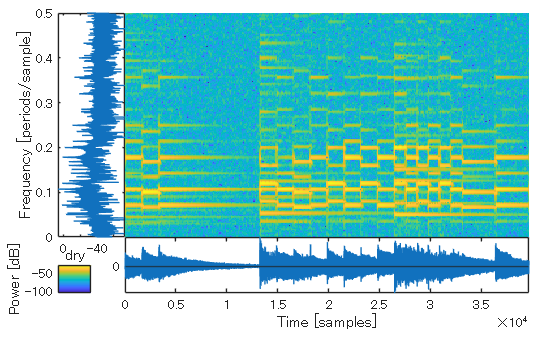

F.plot(ss{1}); title("dry"); 

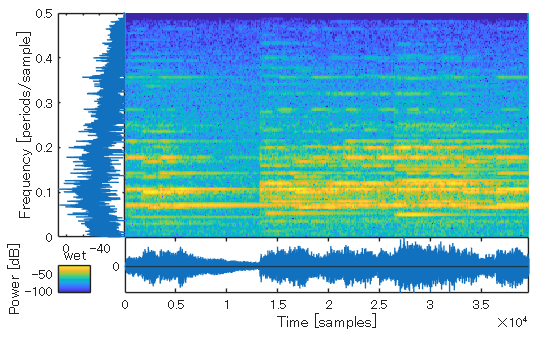

%saveas(gcf, "result/" + sprintf(audiofilename,1) + "_dry.png")
F.plot(obs{1}(1:len_ss)); title("wet"); 

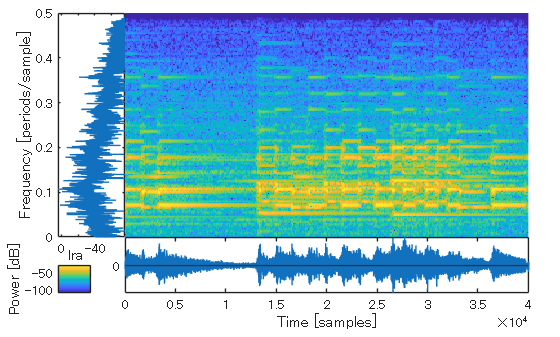

%saveas(gcf, "result/" + sprintf(audiofilename,1) + "_wet.png")
F.plot(ret{1}); title("lra");

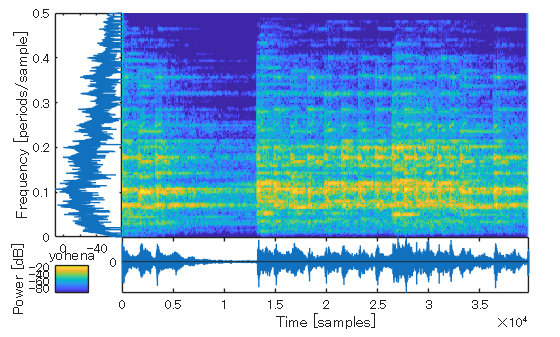

%saveas(gcf, "result/" + sprintf(audiofilename + "_ORACLE_ret_pad=%d.png",1, padding) )
F.plot(ret_lift{1}); title("yohena");

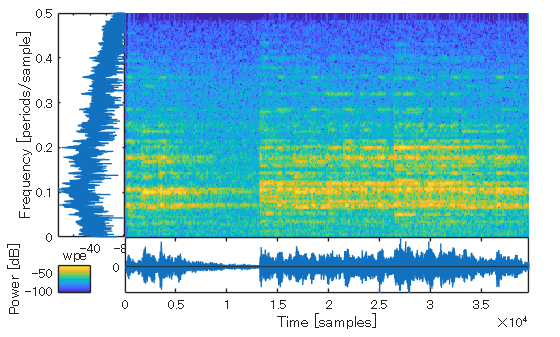

%saveas(gcf, "result/" + sprintf(audiofilename + "_ORACLE(w)_ret.png",1, padding) )
F.plot(ret_wpe{1}(1:len_ss)); title("wpe");

- どの結果も時間のマイナス方向に信号が漏れ出ているのがきになる．

- weight をいれることで若干改善．ただ，きいてもわからない